EXPERIMENT NO 4

Circular convolution

a)concentric circle method

clc;
clear all;
close all;
x=input("Enter the elements in x[n]:");
x_ind=input("Enter the index of x[n]:");
h=input("Enter the elements in h[n]:");
h_ind=input("Enter the index of h[n]:");
x1=x;
x=x(:,end:-1:1);
for i=1:length(x)
    x=[x(end) x(1:end-1)];
    y(i)=sum(x.*h);
end
disp(y);

    14    16    14    16



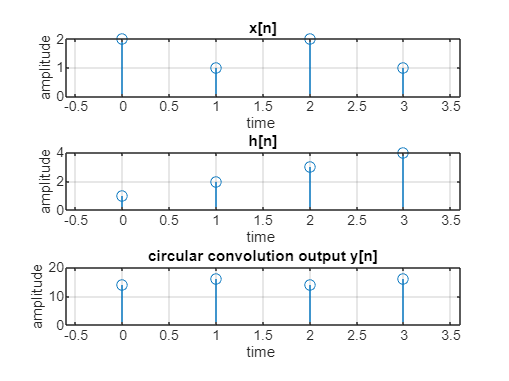

figure;
subplot(3,1,1);
stem(x_ind,x1);
title("x[n]");
xlabel("time ");
ylabel("amplitude");
grid;
subplot(3,1,2);
stem(h_ind,h);
title("h[n]");
xlabel("time ");
ylabel("amplitude");
grid;
subplot(3,1,3);
Ny=0:3;
stem(Ny,y);
title("circular convolution output y[n]");
xlabel("time ");
ylabel("amplitude");
grid;

b)matrix method

x=input("Enter the elements in x[n]:");
x_ind=input("Enter the index of x[n]:");
h=input("Enter the elements in h[n]:");
h_ind=input("Enter the index of h[n]:");
hr=[];
h1=h;
h=h(:,end:-1:1);
for i=1:length(h);
    h=[h(end) h(1:end-1)];
    hr=[hr;h];
end
y=hr*x';
disp(y);

    14
    16
    14
    16



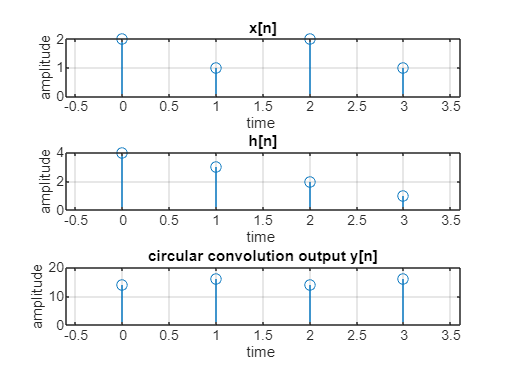

figure;
subplot(3,1,1);
stem(x_ind,x);
title("x[n]");
xlabel("time ");
ylabel("amplitude");
grid;
subplot(3,1,2);
stem(h_ind,h);
title("h[n]");
xlabel("time ");
ylabel("amplitude");
grid;
subplot(3,1,3);
Ny=0:3;
stem(Ny,y);
title("circular convolution output y[n]");
xlabel("time ");
ylabel("amplitude");
grid;

c)using fft

x=input("Enter the elements in x[n]:");
x_ind=input("Enter the index of x[n]:");
h=input("Enter the elements in h[n]:");
h_ind=input("Enter the index of h[n]:");
figure;
subplot(3,1,1);
stem(x_ind,x);
title("x[n]");
xlabel("time ");
ylabel("amplitude");
grid;
subplot(3,1,2);
stem(h_ind,h);
title("h[n]");
xlabel("time");
ylabel("amplitude");
grid;
len_x=length(x);
len_h=length(h);
N=max(len_x,len_h);
new_x=[x zeros(1,N-len_x)];
new_h=[h zeros(1,N-len_h)];
x1=fft(new_x);
h1=fft(new_h);
y1=x1.*h1;
y=ifft(y1);
ny=0:N-1;
disp(y);

    14    16    14    16



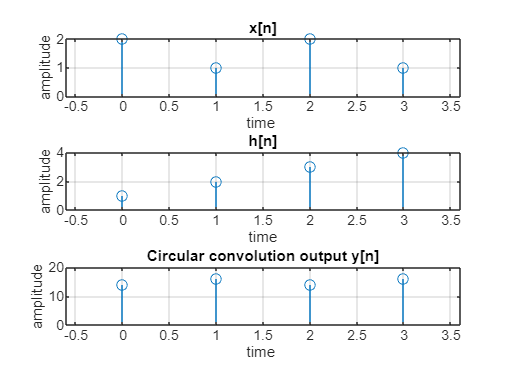

subplot(3,1,3);
stem(ny,y);
title("Circular convolution output y[n]");
xlabel("time ");
ylabel("amplitude");
grid;